dane = audioDatastore("dane\","IncludeSubfolders", true, 'LabelSource','foldernames')

dane =   audioDatastore with properties:

                       Files: {
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00000.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00001.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00002.wav'
                               ... and 997 more
                              }
                     Folders: {
                              ' ...\Jakub Poćwiardowski\MATLAB\Projects\BayesMusicClassification\dane'
                              }
                      Labels: [blues; blues; blues ... and 997 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[daneTrain, daneTest] = splitEachLabel(dane,0.8);
[x,xinfo] = read(daneTrain);
xinfo

xinfo = struct with fields:
    SampleRate: 22050
      FileName: 'C:\Users\Jakub Poćwiardowski\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00000.wav'
         Label: blues


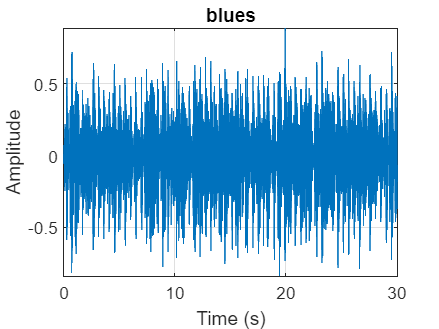

%sound(x,xinfo.SampleRate)

t = (0:numel(x)-1)/xinfo.SampleRate;
figure
plot(t,x)
title(xinfo.Label)
grid on
axis tight
ylabel("Amplitude")
xlabel("Time (s)")

% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",xinfo.SampleRate, ...
    "linearSpectrum",true,"melSpectrum",true, ...
    "mfcc",true,"mfccDelta",true, ...
    "mfccDeltaDelta",true,"spectralCentroid",true, ...
    "spectralCrest",true,"spectralFlatness",true, ...
    "spectralFlux",true,"spectralSkewness",true, ...
    "spectralSlope",true,"pitch",true, ...
    "harmonicRatio",true,"zerocrossrate",true, ...
    "shortTimeEnergy",true);


featureMatrix = extract(extractor,x);
[numWindows,numFeatures] = size(featureMatrix)

numWindows = 1291

numFeatures = 594

features = extract(extractor,x)

features = 1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

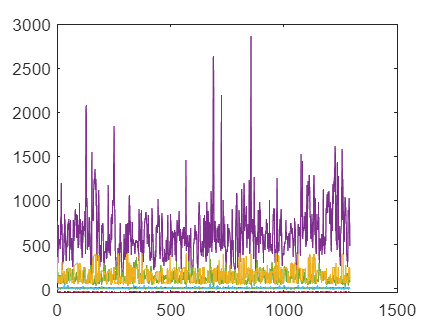

plot(features)


%daneTrainT = transform(daneTrain,@(x){extract(extractor,x)})
%features = readall(daneTrainT,UseParallel=pFlag)